%Load the dataset
data = load("visiblehuman.mat");
dataHead = data.head;
dataFresh = data.head_fresh;
dataFrozen = data.head_frozen;
dataMRI = data.head_mri;

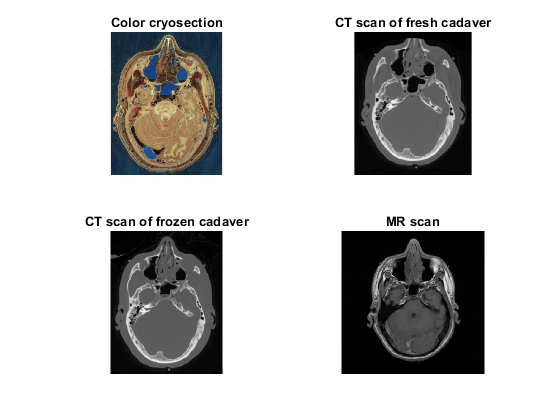

%Visualize the data
figure();
subplot(2, 2, 1);
imshow(dataHead), title("Color cryosection");
subplot(2, 2, 2);
imshow(dataFresh), title("CT scan of fresh cadaver");
subplot(2, 2, 3);
imshow(dataFrozen), title("CT scan of frozen cadaver");
subplot(2, 2, 4);
imshow(dataMRI), title("MR scan");

%Load the annotated points, save them in their respective matrices and
%calculate the mean landmarks
data1 = load("SelPointsG.mat");
data2 = load("SelPointsM.mat");
data3 = load("SelPointsZ.mat");

%Load landmarks for Color Cryosection
ColCryo = zeros([10 2 3]);
ColCryo(:, :, 1) = data1.ColCryoPoints;
ColCryo(:, :, 2) = data2.ColCryoPoints;
ColCryo(:, :, 3) = data3.ColCryoPoints;
ColCryoMean = mean(ColCryo, 3);

%Load landmarks of fresh cadaver CT scan
CTFresh = zeros([10 2 3]);
CTFresh(:, :, 1) = data1.CTFreshPoints;
CTFresh(:, :, 2) = data2.CTFreshPoints;
CTFresh(:, :, 3) = data3.CTFreshPoints;
CTFreshMean = mean(CTFresh, 3);

%Load landmarks of frozen cadaver CT scan
CTFrozen = zeros([10 2 3]);
CTFrozen(:, :, 1) = data1.CTFrozenPoints;
CTFrozen(:, :, 2) = data2.CTFrozenPoints;
CTFrozen(:, :, 3) = data3.CTFrozenPoints;
CTFrozenMean = mean(CTFrozen, 3);

%Load landmarks for MR scan
MRI = zeros([10 2 3]);
MRI(:, :, 1) = data1.MRPoints;
MRI(:, :, 2) = data2.MRPoints;
MRI(:, :, 3) = data3.MRPoints;
MRIMean = mean(MRI, 3);

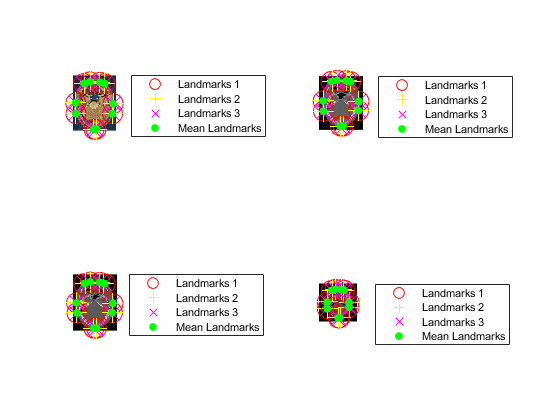

%Visualize the landmarks
figure();
subplot(2, 2, 1);
ShowLandmarks(dataHead, ColCryo);
subplot(2, 2, 2);
ShowLandmarks(dataFresh, CTFresh);
subplot(2, 2, 3);
ShowLandmarks(dataFrozen, CTFrozen);
subplot(2, 2, 4);
ShowLandmarks(dataMRI, MRI);


%Calculate the Fiducial localization error (FLE)
[f, sig] = FiducialLocalizationError(ColCryo)

f =    11.9176   -0.9032
   -0.9032    1.9567


sig = 6.9372

%Obtain parameters which would register the MR image to the frozen CT image using
%a similarity transform (scaling, rotation and translation)
disp("Optimal parameters to transform MRI to frozen CT scan");

Optimal parameters to transform MRI to frozen CT scan


[s, R, t] = SimilarityTransform(MRIMean, CTFrozenMean)

s = 1.6012

R =     0.9930   -0.1185
    0.1185    0.9930


t =    -9.1335
    2.0905



FiducialRegistrationError(MRIMean, CTFrozenMean)

ans = 576.7936


disp("Optimal parameter to transform frozen CT scan to MRI");

Optimal parameter to transform frozen CT scan to MRI


[s, R, t] = SimilarityTransform(CTFrozenMean, MRIMean)

s = 0.5837

R =     0.9930    0.1185
   -0.1185    0.9930


t =    13.6889
    6.1549



FiducialRegistrationError(CTFrozenMean, MRIMean)

ans = 113.6438

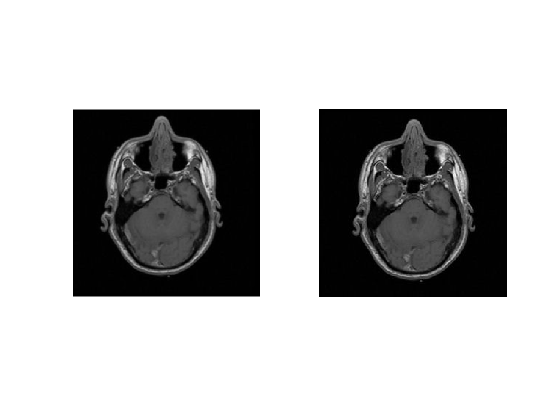

%Visualize the transformed image
figure();
subplot(1, 2, 1);
imshow(MRITransform);
subplot(1, 2, 2);
imshow(dataMRI);

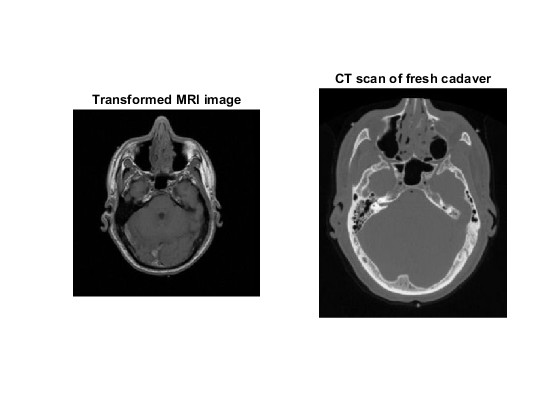


figure();
subplot(1, 2, 1);
imshow(MRITransform), title("Transformed MRI image");
subplot(1, 2, 2);
imshow(dataFresh), title("CT scan of fresh cadaver");

size(MRITransform)

ans =    311   311


size(dataFresh)

ans =    338   277


%Visualize the RGB image